1.2 Discrete-Time Sinusoidal Signals

Discrete-time complex exponentials play an important role in the analysis of discrete-time signals and systems.

A discrete-time complex exponential has the form $a^n$, where α is a complex scalar. The discrete-time and

consine signals can be build from complex exponential signals by setting $a = e^{\pm iw}$ , namely:

                                                                
$$cos(\omega n) = \frac{1} {2}(e^{i\omega n}+e^{-i\omega n})$$


                                                               
$$sin(\omega n) = \frac{1} {2i}(e^{i \omega n}-e^{-i \omega n})$$


In this exercise, you will create and analyze a number of discrete-time sinusoids. There are many similarities

beween continuous-time and discrete-tiime sinusoids. However, you will also examine some the important

differences between sinusoids in continuous and discrete time in this exercise.

1.2a Consider the discrete-time signal

                                                                        
$$x_M[n]=sin(\frac{2\pi Mn}{N})$$


and assume N=12. For M=4,5,7 and 10, plot $x_M[n]$ on the interval $0\leq n\leq 2N-1$. Use **stem** to creeate your

plots, and be sure to label your axes. What is the fundamental period of each signal? In general, how can the

fundamental period be determined from arbitrary integer values of M and N? Be sure to consider the case in

which M>N.

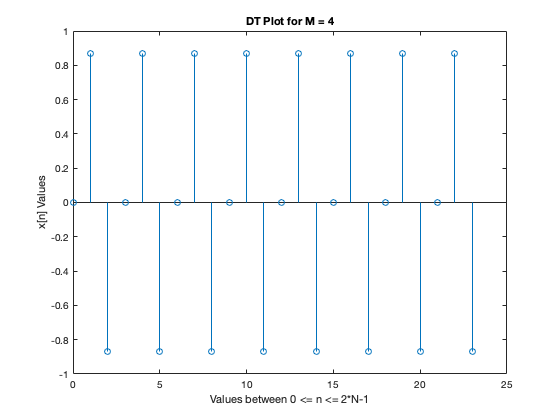

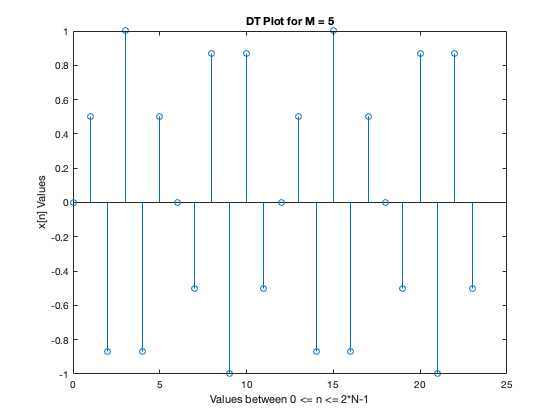

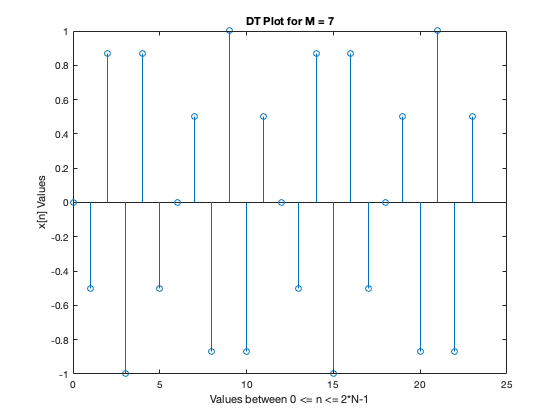

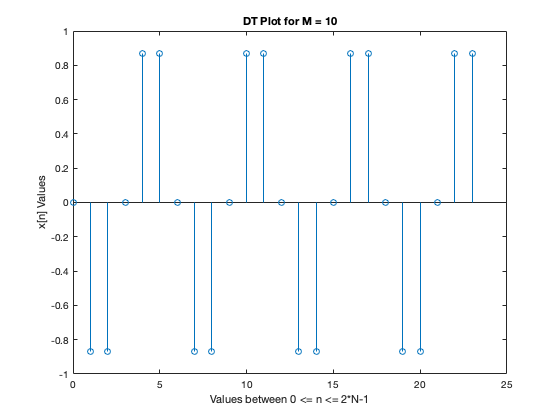

N=12;
M=[4,5,7,10];
n=[0:2*N-1];

%   Period = 2 *pi *k / w0  ==>  w0 = 2 *pi *k / period 

for Mi = M 
    k=1;
    p=N/Mi*k; % p represent the period and Mi= M
    
    w0 =2*pi/p;
    x=sin(w0*n);
    lname= sprintf('DT Plot for M = %i',Mi);
    figure(Mi);
    stem(n,x);
    title(lname);
    ylabel('x[n] Values');
    xlabel('Values between 0 <= n <= 2*N-1');
end

1.2a Fundamental period analysis 

From the illustration we can see:

For x[n] where M=5 and N=12, the funcamental period is 12 when m=5.  

For x[n] where M=7 and N=12, the funcamental period is 12 when m=7.

For x[n] where M=10 and N=12, the funcamental period is 6 when m=5..

 For x[n] where M=15 and N=12, the funcamental period is 4 when m=5.

1.2b Consider the signal

                                                                  
$$x_k[n]=sin(\omega_kn)$$


where $\omega _k = 2\pi k /5$. For  $x_k[n]$ given by k=1,2,4, and 6, use stem to plot each signal on the interval 0<= n <= 9. All

of the signals should be plotted with separate axes in the same figure using subplot. How many unique signals have you plotted?

 If two signals are identical, explain how different values can yield the same signal.

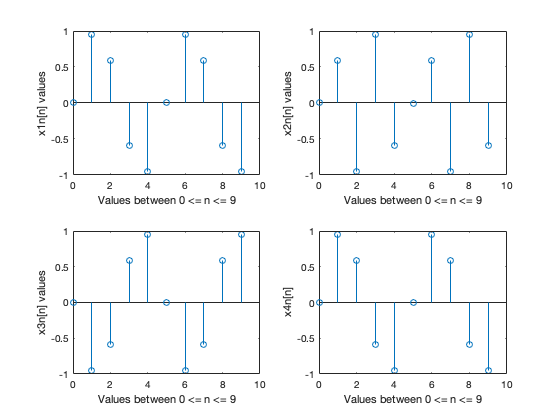

%
%   define k as k = [1,2,4,6] 
%
%   define the limits for n, I used 0<= n <= 9
%   in k loop
%   define  wk = 2 *pi *k/5
%   define the signal xn 
%   use the stem to plot DT signal
%   label the axis and titles
%
n=[0:9];

k1=1;
wk=2*pi*k1/5;
x1n=sin(wk*n);
subplot(2,2,1); 
stem(n,x1n);
xlabel('Values between 0 <= n <= 9');
ylabel('x1n[n] values');

k2=2;
wk=2*pi*k2/5;
x2n=sin(wk*n);
subplot(2,2,2); 
stem(n,x2n);
xlabel('Values between 0 <= n <= 9');
ylabel('x2n[n] values');

k3=4;
wk=2*pi*k3/5;
x3n=sin(wk*n);
subplot(2,2,3); 
stem(n,x3n);
xlabel('Values between 0 <= n <= 9');
ylabel('x3n[n] values');

k4=6;
wk=2*pi*k4/5;
x4n=sin(wk*n);
subplot(2,2,4); 
stem(n,x4n);
xlabel('Values between 0 <= n <= 9');
ylabel('x4n[n]'); 

1.2b Result analysis

We can see from illustration:

 a) There are 3 unique signals .

b) $x_1[n] \ and\ x_6[n]$ signals are identical.

        
$$x_6[n]= sin(2\pi6/5)=sin(2\pi/5)=x_1[n]$$
 

1.2c.

Now consider the flollowing signals:

                                                          
$$x_1[n]= cos(\frac{2\pi n}{N}) +2cos(\frac{3\pi n}{N})$$


                                                          
$$x_2[n]= 2cos(\frac{2n}{N}) +cos(\frac{3n}{N})$$


                                                          
$$x_3[n]= cos(\frac{2\pi n}{N}) +3sin(\frac{5\pi n}{2N})$$


Assume N=6 for each signal. Determine whether or not each signal is periodic. If a signal is perriodic, plot the

signal for two period, starting at n=0. If the signal is not periodic plot the signal $0\leq n\leq 4$N and explain why it is

not periodic. Remeber to use stem and to appropriately label your axes.

If period $P= 2\pi k /\omega_0$ rational, $x_i[n]$ is periodic.

To calculate the period of $x_1[n]$ we check the signals ,  for $cos(\frac{2\pi n}{N}) $ ,  $\omega_0 =2\pi/N$and $P=kN$, that concludes P is rational, the same way $2cos(\frac{3\pi n}{N})$ is periodic and $P =\frac{3kN}{2}$, P is rational

For that reason $x_1[n]$ periodic.

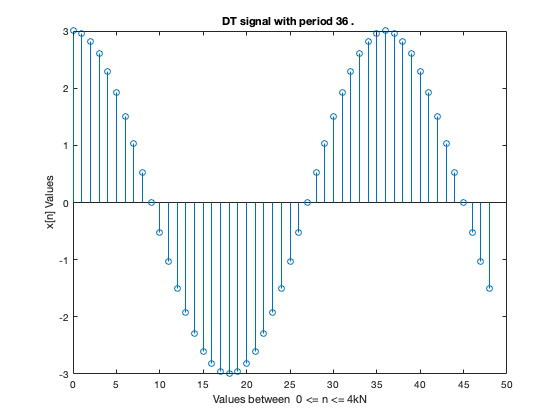

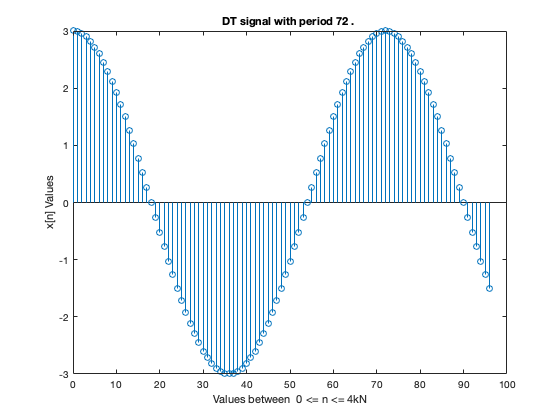

%
%   define k as k = [2,4] because we need to plot 2 different signal with
%   different periods
%
%   define the limits for n, I used 0<= n <=4*N
%
%   in k loop
%   define the period that already calculated as P1 =kN and P2= 3kN/2 (k = 2 or 4 )
%   Period P = LCM(P1,P2)
%   define w0 using period formula  w0 = 2pi/ P 
%   
%   define the signal x1n 
%   use the stem to plot DT signal
%   label the axis and titles
%
k=[2,4];
N=6;
for i=k
    p1= i*N;n=[0:4*i*N];
    p2=3*i*N/2;
    p=lcm(p1,p2);
    figure(i);
    w0= 2*pi/p;
    x1n=cos(w0*n)+2*cos(w0*n);
    stem(n,x1n);
    titletext= sprintf('DT signal with period %d . ', p);
    title(titletext);
    ylabel('x[n] Values');
    xlabel('Values between  0 <= n <= 4kN');
    
end

To calculate the period of $x_3[n]$ we check the signals ,  for $cos(\frac{2\pi n}{N}) $ ,  $\omega_0 =2\pi/N$and $P=kN$, that concludes P is rational, the same way $3cos(\frac{5\pi n}{2N})$ is periodic and $P =\frac{4kN}{5}$, P is rational

For that reason $x_3[n]$ periodic.

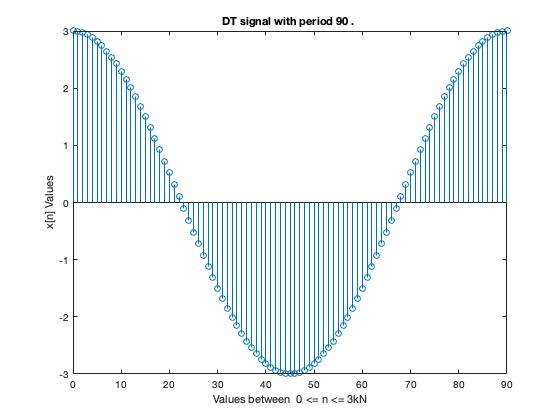

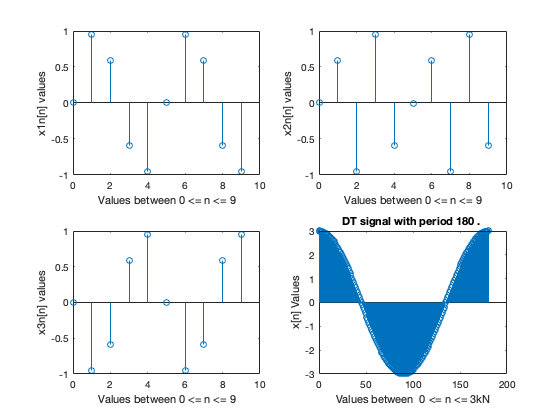

% 
%   define k as k = [5,10] because we need to plot 2 different signal with
%   different periods
%
%   define the limits for n, I used 0<= n <=4*k*N for beter visualization
%
%   in k loop
%   define the period that already calculated as P1 =kN and P2= 4kN/5 (k = 5 or 10 )(that makes P =4N or 8N) 
%   Period P = LCM(P1,P2)
%   define w0 using period formula  w0 = 2pi/ P 
%   
%   define the signal x1n = cos(w0n) +2cos(w0n) 
%   use the stem to plot DT signal
%   label the axis and titles
%
k=[5,10];
N=6;

for i=k
    n=[0:3*i*N];
    p1= i*N;
    p2=3*i*N/2;
    p=lcm(p1,p2);
    w0= 2*pi/p;
    x3n=cos(w0*n)+2*cos(w0*n);
    figure(i);
    stem(n,x3n);
    titletext= sprintf('DT signal with period %d . ', p);
    title(titletext);
    ylabel('x[n] Values');
    xlabel('Values between  0 <= n <= 3kN');
    
end

To calculate the period of $x_2[n]$ we check the signals ,  for $2cos(\frac{2 n}{N}) $ ,  $\omega_0 =2/N$and $P=kN\pi$, that concludes P is not rational, for that reason $x_2[n]$ cannot be periodic.

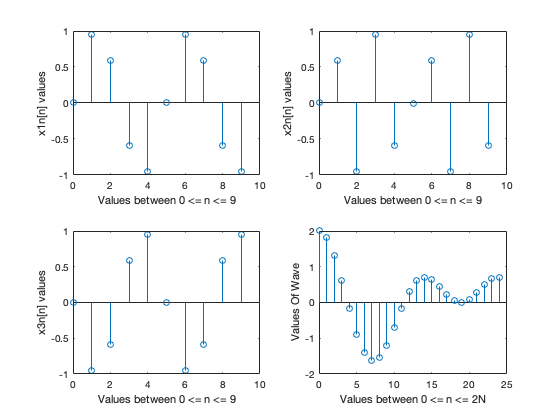

N=6;
n=[0:4*N];
x2n= cos(2*n/N)+cos(3*n/N);
stem(n,x2n);
ylabel('Values Of Wave');
xlabel('Values between 0 <= n <= 2N');

1.2d

Plot each of the followinging signals on the inerval   $0\leq n \leq 31$:

                                                            
$$x_1[n]= sin(\frac{\pi n}{4}) cos(\frac{\pi n}{4})$$
    

                                                            
$$x_2[n]= cos^2(\frac{\pi n}{4})$$


                                                            
$$x_3[n]= sin(\frac{\pi n}{4}) cos(\frac{\pi n}{8})$$


What is the fundamental period of each signal? For each of these three signals, how could you have

determined the fundamental period without relyong upon the MATLAB?

Without using MATLAB, we can use the gernal formular to determine if a signal is periodic and its fundamental

period.

$w_kn = 2\pi m$, where m is an integer. Let's see how it works.

(A)   $x_1[n]= sin(\frac{\pi n}{4}) cos(\frac{\pi n}{4})=1/2sin(2\frac{\pi n}{4})=1/2sin(\frac{\pi n}{2})$

so we need to fine the smallest m where $\pi n /2 = 2 \pi m$ . # $n=4m$, so the fundament period is 4 as shown in the

plot.

(B) Given $cos(2x)=2cos^2(x)-1$, we have $cos^2(x)=\frac{cos(2x)-1}{2}$.

We have $x^2[n]=cos^2(\frac{\pi n}{4})=\frac{cos(\pi n /2)-1}{2}$. therefor $\pi n /2 = 2 \pi m$ . # $w_kn=2\pi m$ , so the fundament period is 4 as

shown in the plot.

(c) For $x_3[n]=sin(\frac{\pi n}{4})cos(\frac{\pi n}{8})$, we can apply the above general formular $w_kn=2\pi m$ to both sin and cos part of

the signal, where we have n=8m and n'=16m', so LCM(8,16)=16. Therefore the fundamental period is 16 which

makes both the cos and and sin part fo the signals are periodic.

1.3 Transormations of the time index for Discrete-Time Signals

1.3a

Define a MATLAB vector $nx$ to be the time indices $-3 \leq  n \leq 7$ and the MATLAB vector x to be the values of the

signal x[n] is given by

                                                         
$$\[x[n] = 
 \begin{cases} 

      2 &   n=0 \\
      1 & n=2 \\
      -1 &   n=3\\
      3 & n=4\\
     0 & otherwise
     \end{cases}
\]$$


If you defined these vectors correctly, you should be able to plot this discreta-time sequence by typing

stem(nx,x), The resulting plot should match the plot show below.

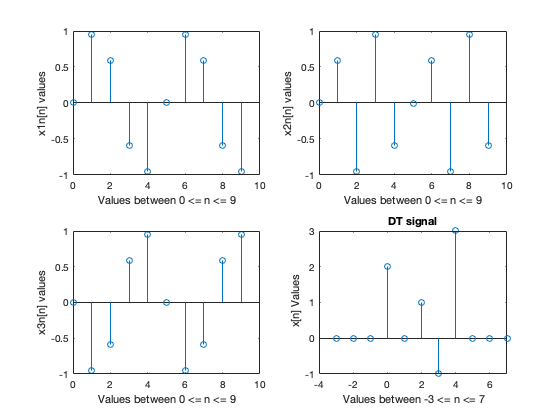

xn=[-3:7];
x=[];
for i=xn
    switch(i)
        case 0
            x=[x, 2];
        case 2
            x=[x, 1];
        case 3
            x=[x, -1];
        case 4
            x=[x, 3];
        otherwise
            x=[x, 0];
    end
end
stem(xn,x)
title('DT signal');
ylabel(' x[n] Values');
xlabel(' Values between -3 <= n <= 7');

1.3b˜

For this part, you will define MATLAB vectors y1 through y4 to represent the following discrete-time signals:

                                                                        
$$y_1[n]=x[n-2]$$


                                                                        
$$y_2[n]=x[n+1]$$


                                                                        
$$y_3[n]=x[-n]$$


                                                                        
$$y_4[n]=x[-n+1]$$


To do this, you should define y1 through y4 to be equal to x. The key is to define correctly the corresponding

index vectors ny1 through ny4. First you should figure out how the index of a given sample of x[n] changes

when transforming to $y_i[n]$, The index vectors need not span the same set of indices as nx, bu they shuld all be

at least 11 samples long and include the indeces of all non zero samples of the associated singal.

a = 1;
b = 0;
sub_limit = 1;
upper_limit = 15;
n = [(sub_limit*a)-b: (upper_limit*a)-b];

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


xn = randi([-10 10],1,15);
figure;
stem(n,xn); % virtualization of original signal
y1 = time_management(-2,1,sub_limit,upper_limit);

y1 =      3     4     5     6     7     8     9    10    11    12    13    14    15    16    17


y2 = time_management(1,1,sub_limit,upper_limit)

y2 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14


y3 = time_management(0,-1,sub_limit,upper_limit);

y3 =    -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1


y4 = time_management(1,-1,sub_limit,upper_limit);

y4 =    -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0


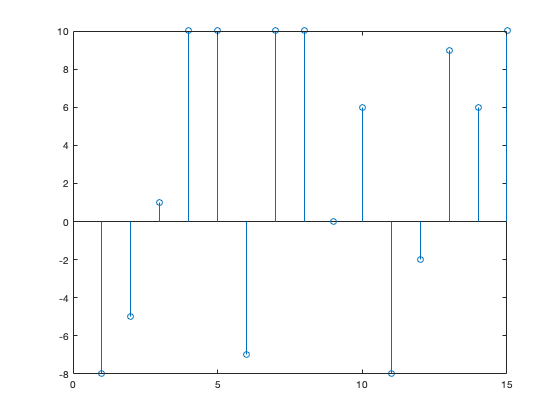

nexttile; stem(y1,xn); ylabel('xn values'); title('delayed 2 value'); 

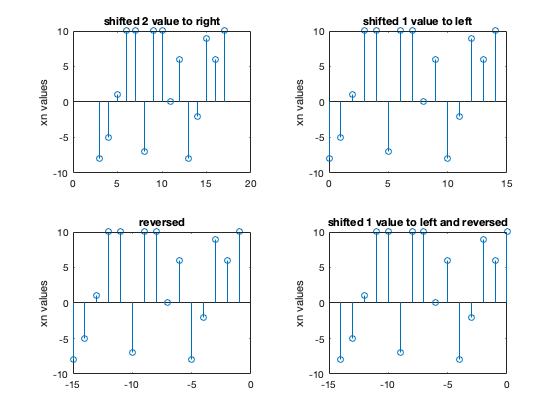

nexttile; stem(y2,xn); ylabel('xn values'); title('advanced 1 value ');
nexttile; stem(y3,xn); ylabel('xn values'); title('reversed'); % 
nexttile; stem(y4,xn); ylabel('xn values'); title('advanced 1 value and reversed');

function [new_n] = time_management(shift_parameter,revers_parameter, sub_limit,upper_limit)
a1 = sub_limit-shift_parameter;
a1 = a1*revers_parameter;
an = upper_limit-shift_parameter;
an = an*revers_parameter;
if(a1<an)
    new_n = [a1:an];

else
    new_n = [an:a1] ;
end
end

1.3b Plots and 1.3c result analysis 

The plots show the relations to x[n] as below: 

1. y1[n] is delayed by 2. 

2. y2[n] is advanced by 1. 

3. y3[n] is flipped. 

4. y4[n] delayed by 1 and then flipped.